%1st violin
[y,Fs] = audioread('violin3.wav');
Amplitude_spectrum_function(y,Fs);

Funda_freq
   261



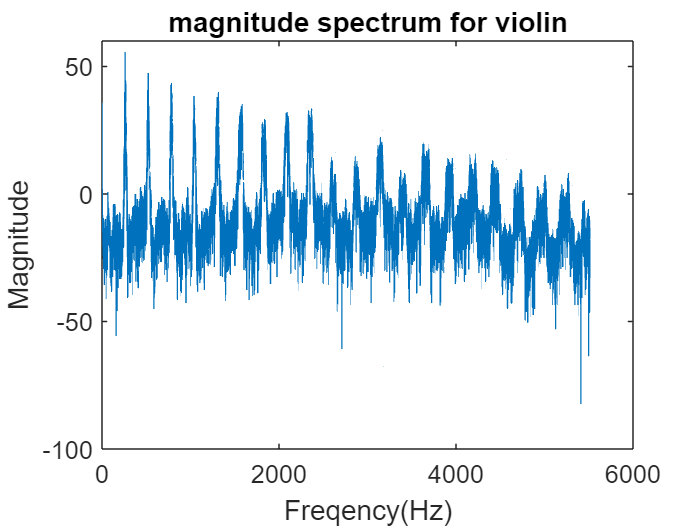

xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for violin")

%flute3
[y2,Fs] = audioread('flute3.wav');
Amplitude_spectrum_function(y2,Fs);

Funda_freq
   793



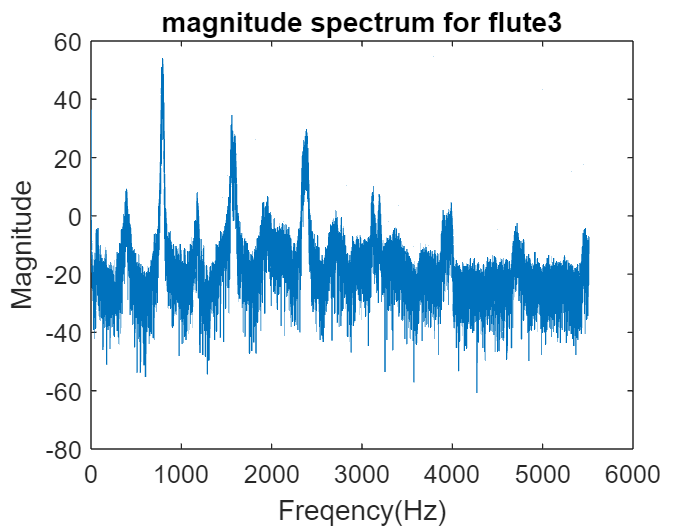

xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for flute3")

%flute1
[y5,Fs] = audioread('flute1.wav');
Amplitude_spectrum_function(y5,Fs);

Funda_freq
        1063



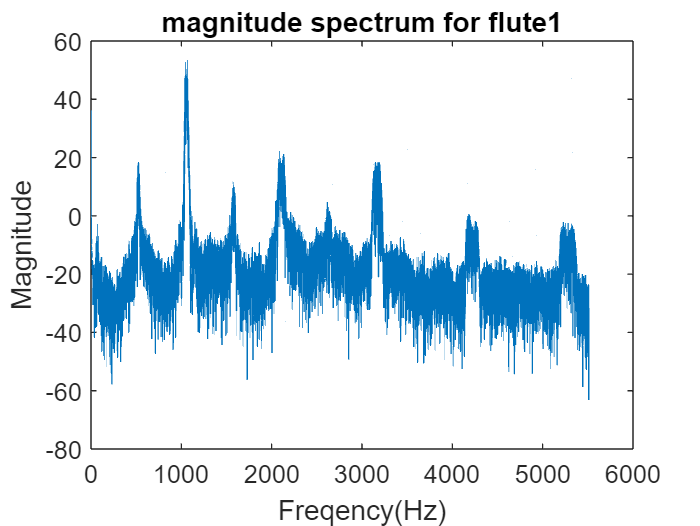

xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for flute1")

%flute2
[y6,Fs] = audioread('flute2.wav');
Amplitude_spectrum_function(y6,Fs);

Funda_freq
   524



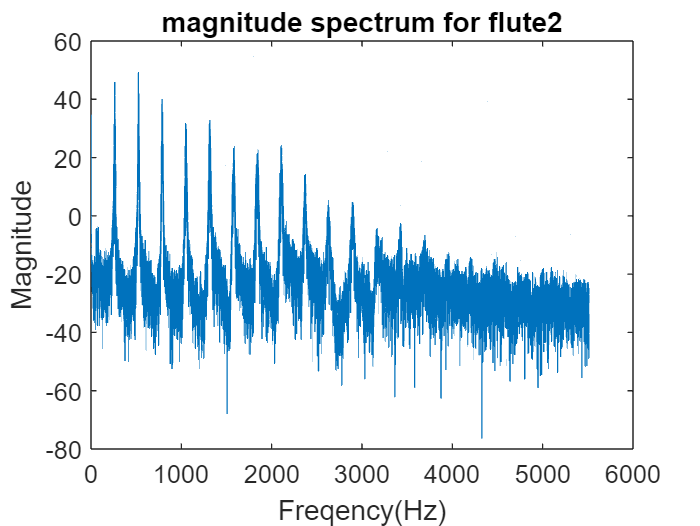

xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for flute2")

%flute4
[y7,Fs] = audioread('flute4.wav');
Amplitude_spectrum_function(y7,Fs);

Funda_freq
   524



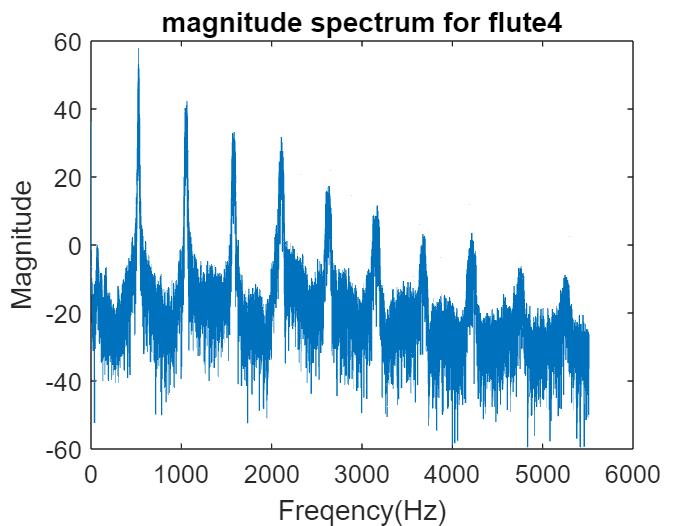

xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for flute4")

%piano
[y3,Fs] = audioread('piano3.wav');
Amplitude_spectrum_function(y3,Fs);

Funda_freq
        1048



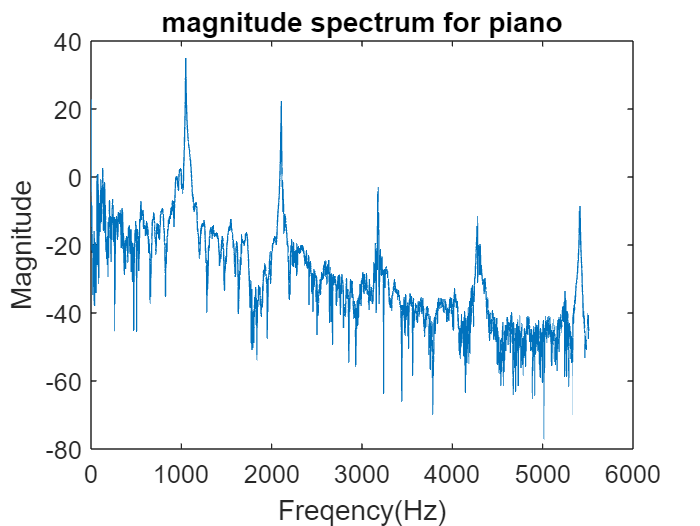

xlabel("Freqency(Hz)");
ylabel("Magnitude");
title("magnitude spectrum for piano");

%trumpet
[y4,Fs] = audioread('trumpet3.wav');
Amplitude_spectrum_function(y4,Fs);

Funda_freq
        1046



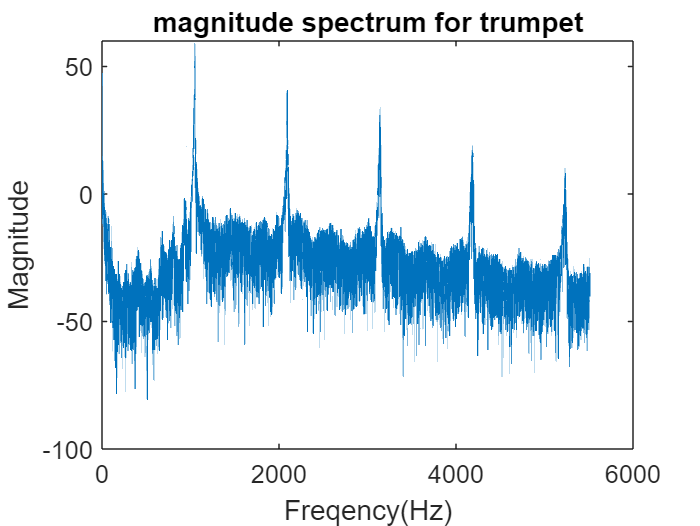

xlabel("Freqency(Hz)");
ylabel("Magnitude");
title("magnitude spectrum for trumpet");

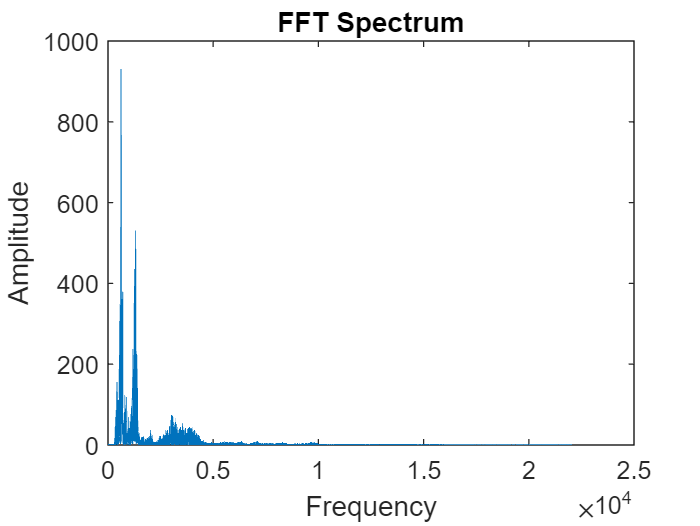


[y2,Fs] = audioread(['rec3.mp4']);
NFFT = length(y2);
Y2 = fft(y2,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs);
magnitudeY2 = abs(Y2);   
plot(F(1:NFFT/2),magnitudeY2(1:NFFT/2));
xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for whistle")

max_whistle = max(magnitudeY2);
recorded = F(magnitudeY2==max_whistle(1,1));
recorded = recorded(1,1)

recorded = 296.8788

recordedl = recorded*0.95

recordedl = 282.0349

recordedu = recorded*1.05

recordedu = 311.7228

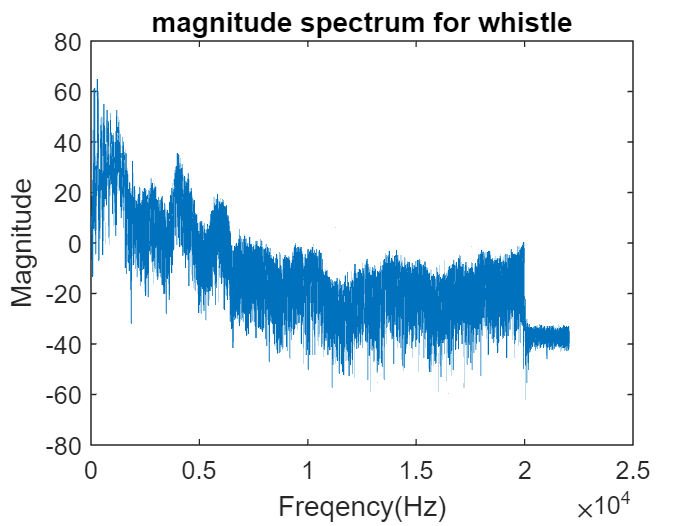

[y2,Fs] = audioread(['rec3.mp4']);
Amplitude_spectrum_function(y2,Fs);
xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for whistle")

recorded=5018;
recordedl = recorded*0.95

recordedl = 4.7671e+03

recordedu = recorded*1.05

recordedu = 5.2689e+03

%2c
Fs=44100;
info = audiodevinfo;
recObj = audiorecorder(Fs,8,1)

recObj =   audiorecorder with properties:

       SampleRate: 44100
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


recDuration = 4;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.



play(recObj)

ans =   audioplayer with properties:

       SampleRate: 44100
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 176400
          Running: 'on'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


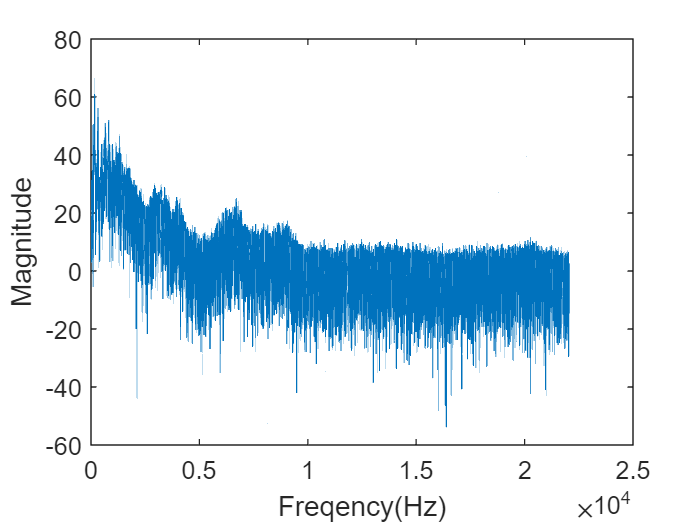


y = getaudiodata(recObj);
NFFT = length(y);
Y = fft(y,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs);
magnitudeY = abs(Y);
mag_db= 20.*log10(magnitudeY);
Out = plot(F(1:NFFT/2),mag_db(1:NFFT/2));
xlabel("Freqency(Hz)");
ylabel("Magnitude");

max_mag = max(mag_db);
recorded1 = F(mag_db==max(mag_db));
fundamental_freq = fix(recorded1(1,1));
disp("Funda_freq");

Funda_freq


disp(fundamental_freq);

   162




if and(fundamental_freq>recordedl, fundamental_freq<recordedu)
    disp("ACCESS GRANTED")
else
    disp("ACCESS DENIED")
end

ACCESS DENIED


%dont consider
y = audioread('Opera.wav');
NFFT = length(y)

NFFT = 220500

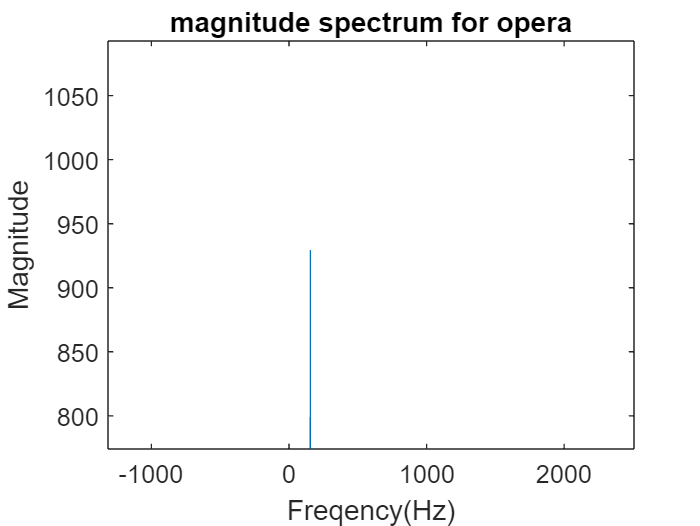

Y = fft(y,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs);
magnitudeY = abs(Y);   
plot(F,magnitudeY);
xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for opera")

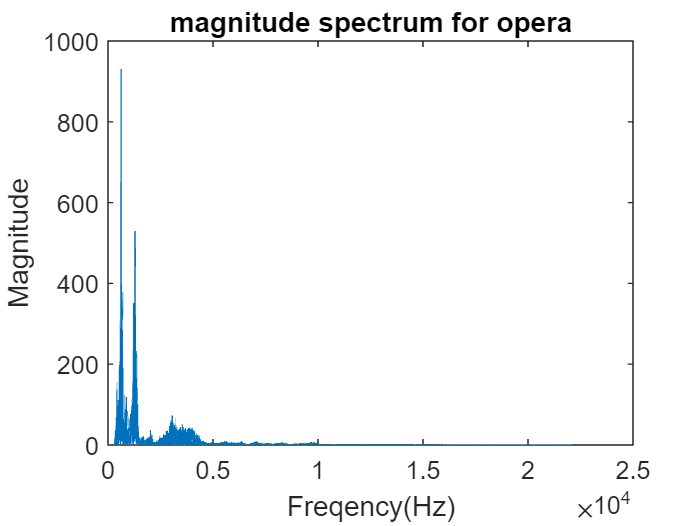



 [y1,fs]=audioread('Opera.wav');
        %t=linspace(0,length(y1)/fs,length(y1));
        Nfft= length(y1); 
        f=linspace(0,fs,Nfft);
        X1=abs(fft(y1));
        plot(f(1:Nfft/2),X1(1:Nfft/2))
        
       xlabel("Freqency(Hz)");
ylabel("Magnitude")
title("magnitude spectrum for opera")

%3a
[y9,fs]=audioread('Opera.wav');
        %t=linspace(0,length(y1)/fs,length(y1));
        Amplitude_spectrum_function(y9,Fs);

Funda_freq
   622



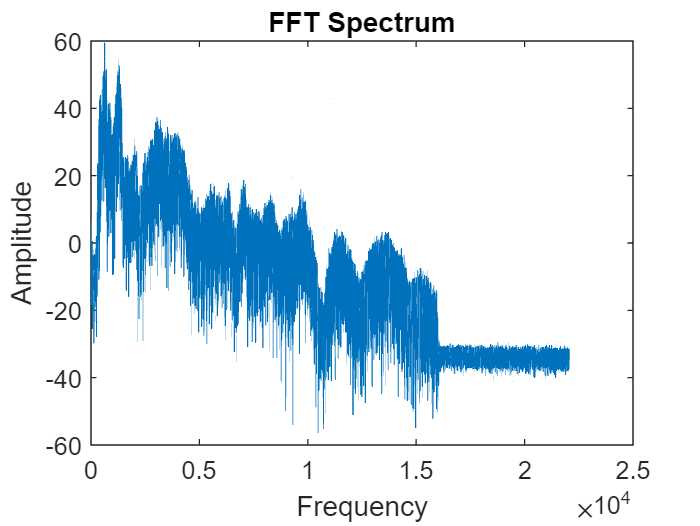

        xlabel('Frequency'); 
        ylabel ('Amplitude');
        title ('FFT Spectrum');

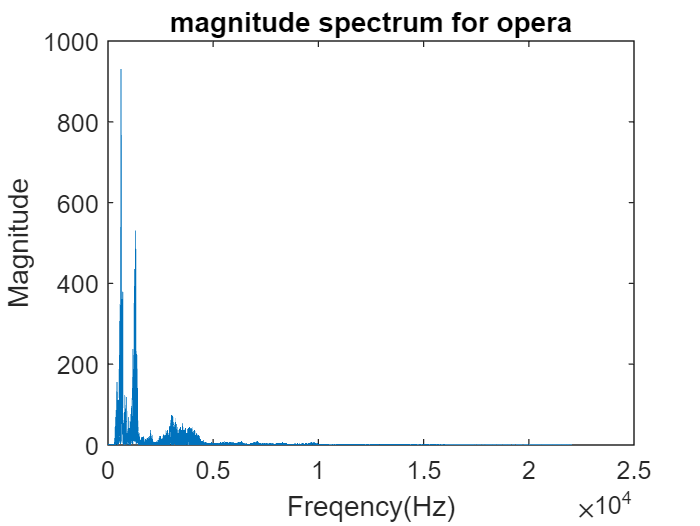

        
        
t = 0:1/fs:2-1/fs;
     
k = spectrogram(y9,20000,2000,5000,fs,'yaxis');
spectrogram(y9,5000,2000,5000,fs,'yaxis')

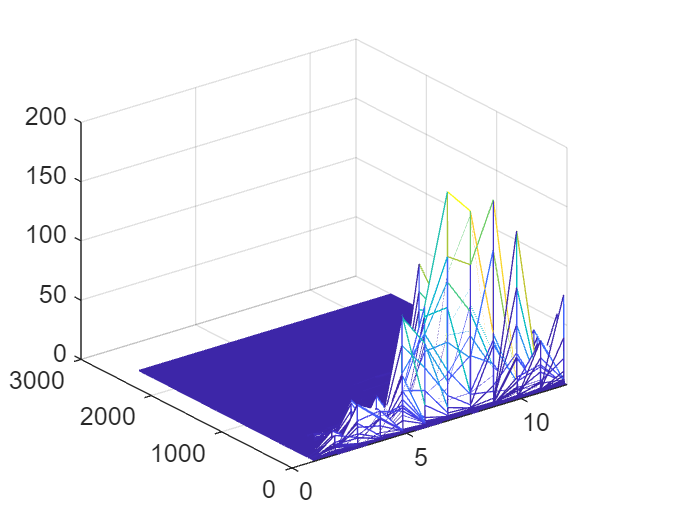

mesh(abs(k))

%3b
